## **LAB1 第一章 信号与系统**

#### 应逸雯12210159 陈薇羽12210460

### 通过本实验的练习，掌握了以下技能：

1.了解如何绘制函数经过时间变换的图像

2.了解直观表达信号处理结果以证明命题、美化图像整齐排版的合理方式

### 作业内容

#### 1.4a 题目要求利用单位冲激函数证明y=sin(x*pi/2)非线性。

分析：x2=2*x1，故对比y2与y1

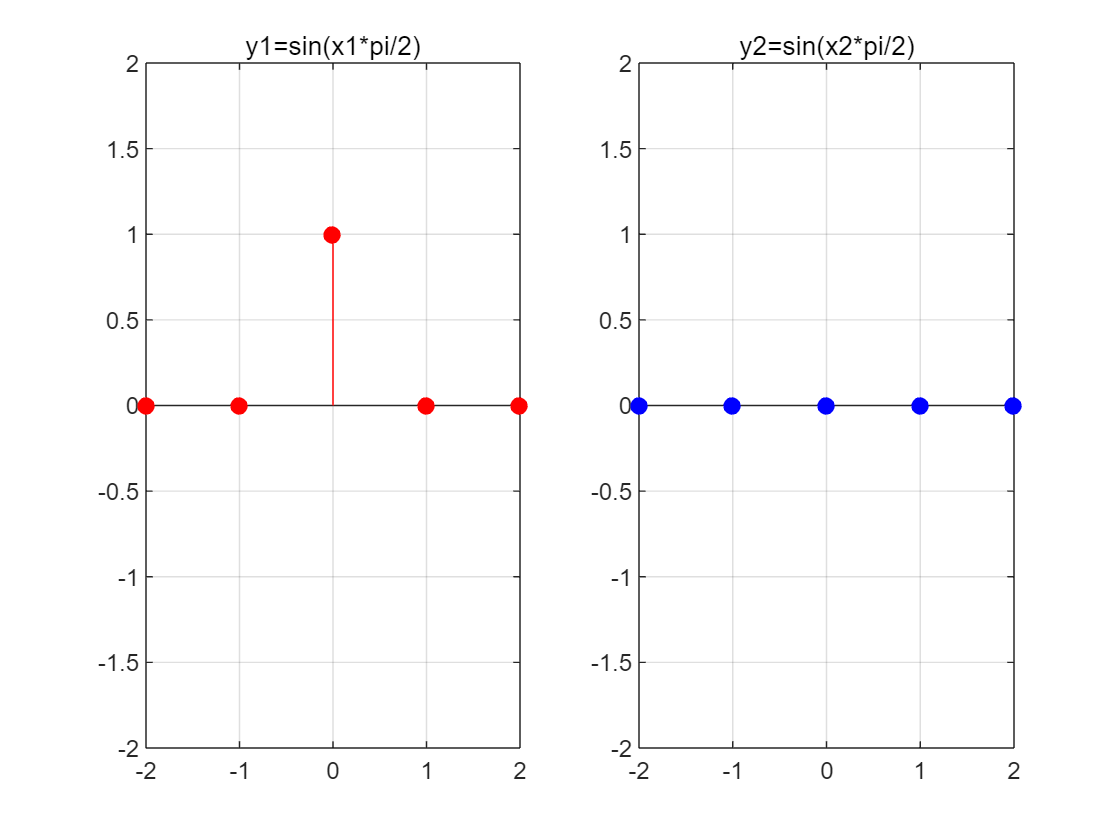

clc,clear,close all
%构造单位冲激函数
x1=[0 0 1 0 0];
x2=[0 0 2 0 0];
nx=-2:1:2;
%构造y=sin(x*pi/2)
y1=sin(x1*pi/2);
y2=sin(x2*pi/2);
%作图比较
figure
subplot(1,2,1),stem(nx,y1,'r','filled'),title('y1=sin(x1*pi/2)');
grid on;
ylim([-2 2]);
subplot(1,2,2),stem(nx,y2,'b','filled'),title('y2=sin(x2*pi/2)');
grid on;
ylim([-2 2]);

结论：若y=sin(x*pi/2)线性，则y2=2*y1，但根据图像，事实并非如此，故y=sin(x*pi/2)非线性。

#### 1.4(b) Use u[n] to prove y[n]=x[n]+x[n+1] not causal.

Draw x[n] and y[n] together to compare.

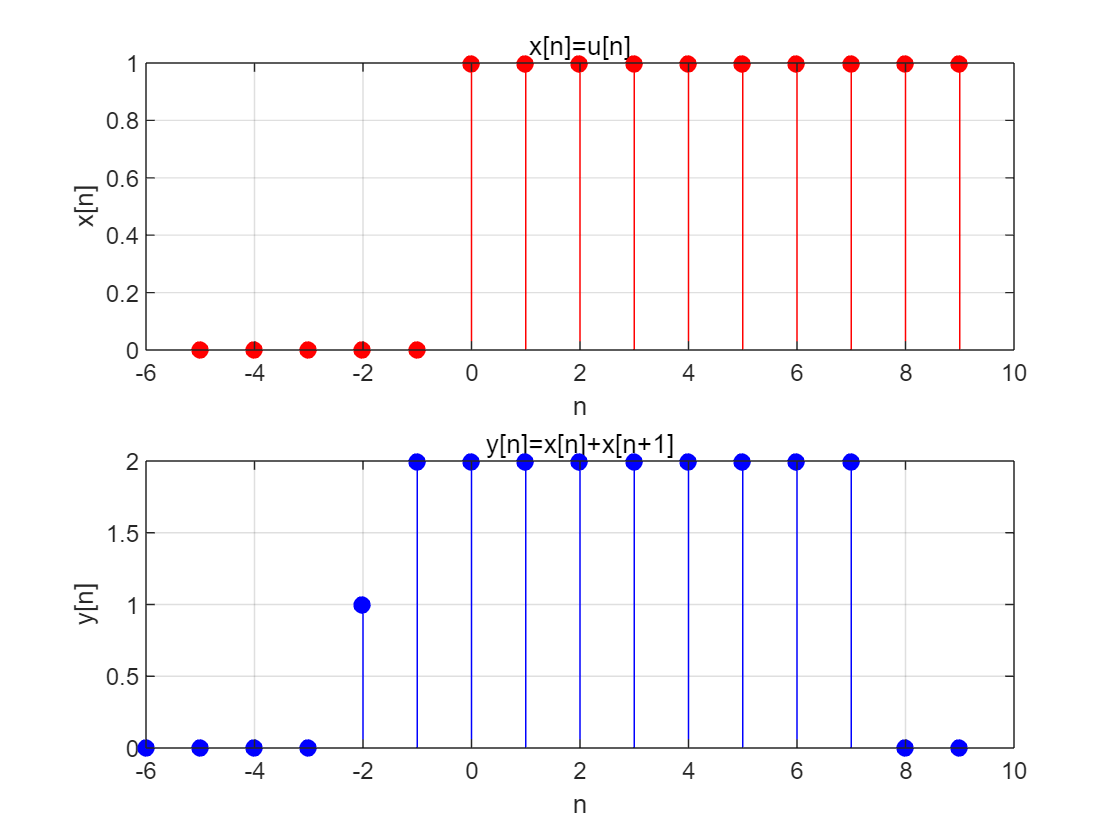

clc,clear,close all
nx=-5:1:9;
ny=-6:1:9;
x=(nx>=0);%构造阶跃函数
y = zeros(size(ny));
%给y赋值
for i = 1:length(nx)-1
    y(i) = x(i) + x(i + 1);
end
figure;
subplot(2,1,1);
stem(nx,x,'r','filled');
xlabel('n');
ylabel('x[n]');
title('x[n]=u[n]');
grid on;
xlim([-6 10]);
subplot(2,1,2);
stem(ny,y,'b','filled');
xlabel('n');
ylabel('y[n]');
title('y[n]=x[n]+x[n+1]');
grid on;
xlim([-6 10]);

because y(-1)=1,x(-1)=0,x(0)=1,which means y(-1) depends on x(0), the system is not casual.

#### 1.4c 证明y[n]=log(x[n])不稳定。

分析：根据理论知识已知，在x趋近于0时log(x)趋近于负无穷，取x[n]=0:0.01:0.5观察log(x[n])

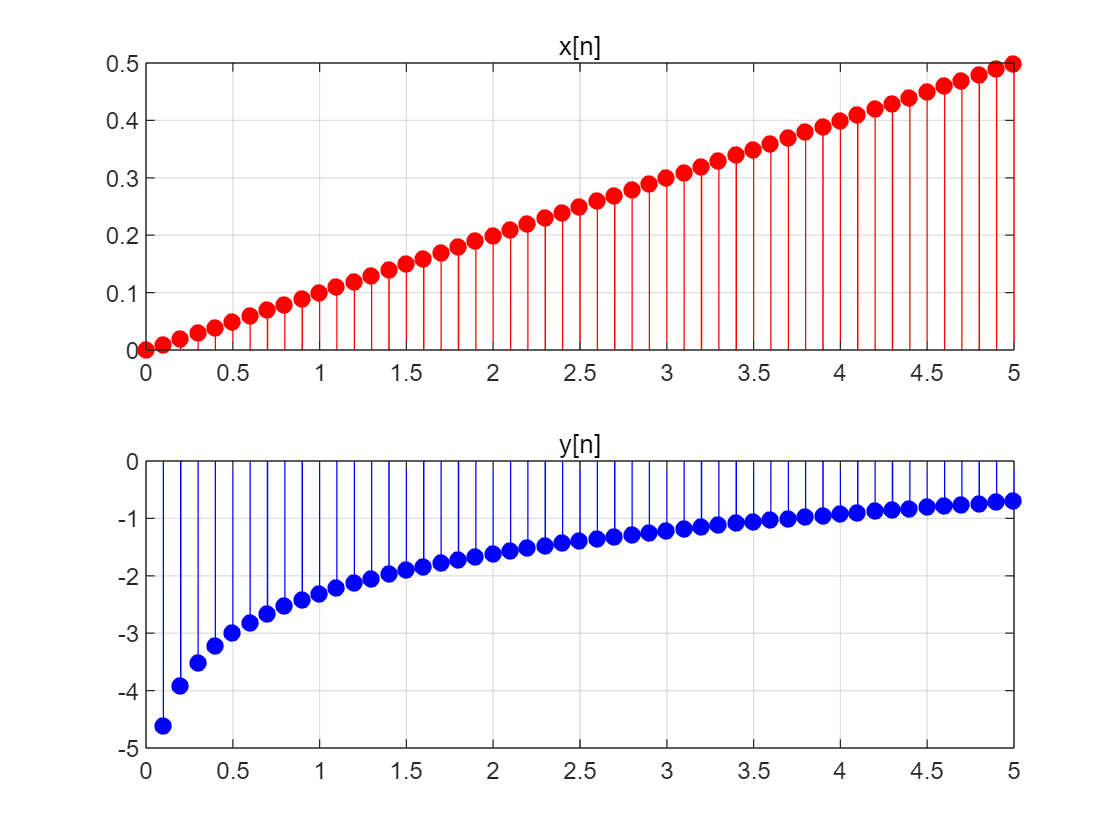

clc,clear,close all
n=0:0.1:5;
x=0.1*n;
y=log(x);
subplot(2,1,1),stem(n,x,'r','filled'),title('x[n]');
grid on;
subplot(2,1,2),stem(n,y,'b','filled'),title('y[n]');
grid on;

当x[n]从x轴正方向趋近于0时，y[n]快速下降且无界，故系统不稳定。

#### 1.4d Prove y[n]=log(x[n]) not invertible.

Consider two different input signals:

x1[n]=1,x2[n]=5

if y1 for x1 equals to y2 for x2, then the system is not invertible

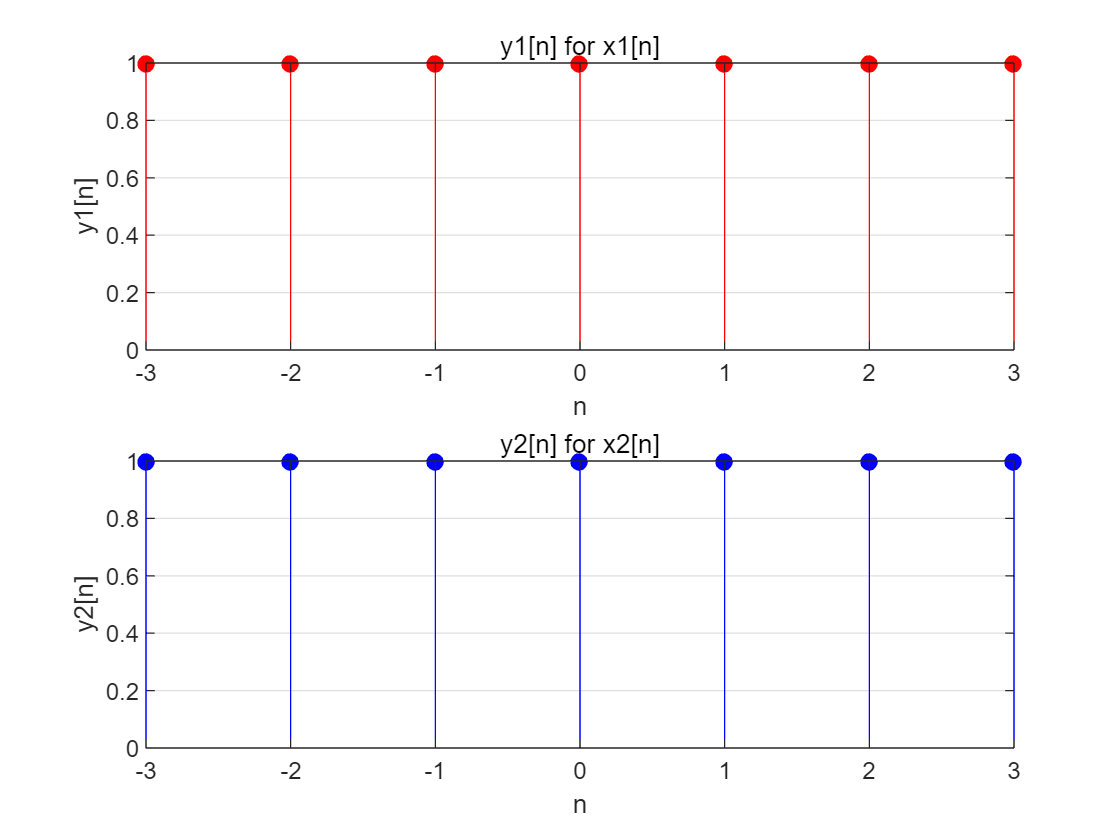

clc,clear,close all
n = -3:3;
x1 = ones(length(n));
x2 = 5*ones(length(n));
y1 = sin(pi/2 * x1);
y2 = sin(pi/2 * x2);
figure;

subplot(2,1,1);
stem(n, y1, 'r','filled');
xlabel('n');
ylabel('y1[n]');
title('y1[n] for x1[n]');
grid on;

subplot(2,1,2);
stem(n, y2, 'b','filled');
xlabel('n');
ylabel('y2[n]');
title('y2[n] for x2[n]');
grid on;

#### 1.5b

分析：根据构造好的函数，代入题目所给的值，绘图

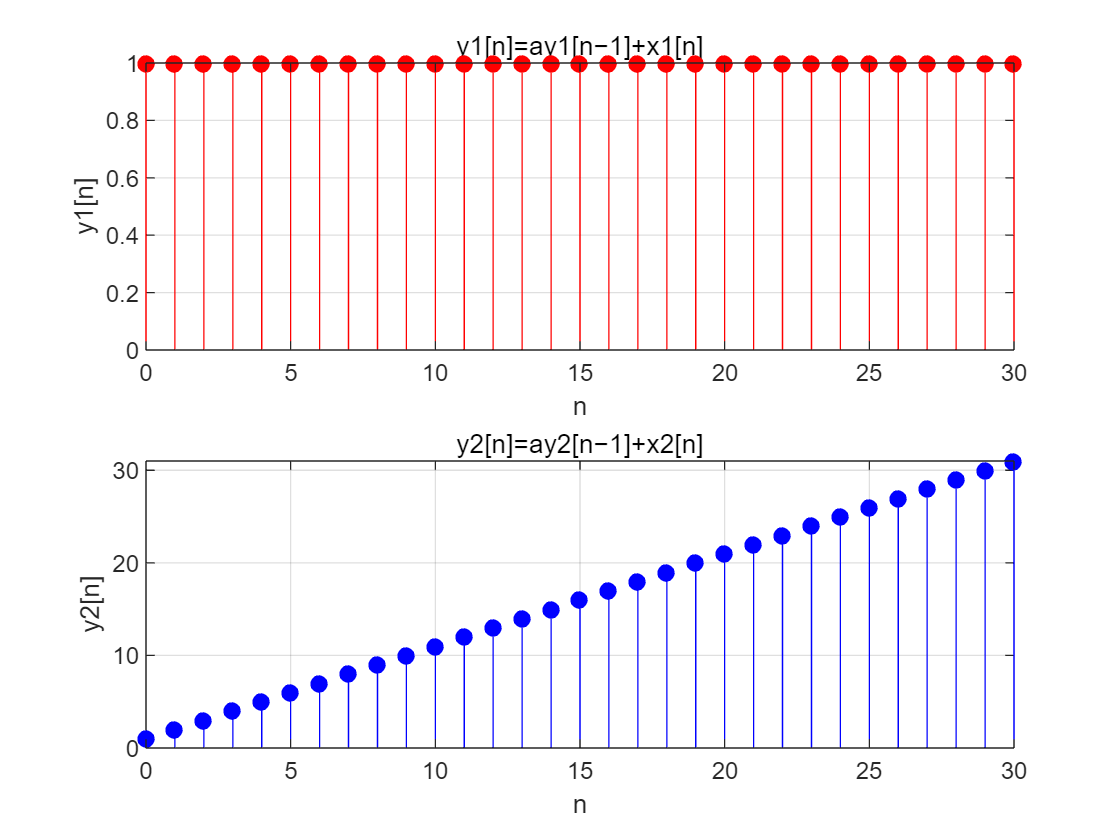

clc,clear,close all
a = 1;
ynl = 0;
n=0:30;
x1 = (n==0); 
x2 = (n>=0);
y1 = diffeqn(a, x1, ynl);
y2 = diffeqn(a, x2, ynl);
figure;
subplot(2,1,1);
stem(n, y1, 'r','filled');
xlabel('n');
ylabel('y1[n]');
title('y1[n]=ay1[n−1]+x1[n]');
grid on;

subplot(2,1,2);
stem(n, y2, 'b','filled');
xlabel('n');
ylabel('y2[n]');
title('y2[n]=ay2[n−1]+x2[n]');
grid on;

#### 1.5c

分析：根据构造好的函数，代入题目所给的值，绘图

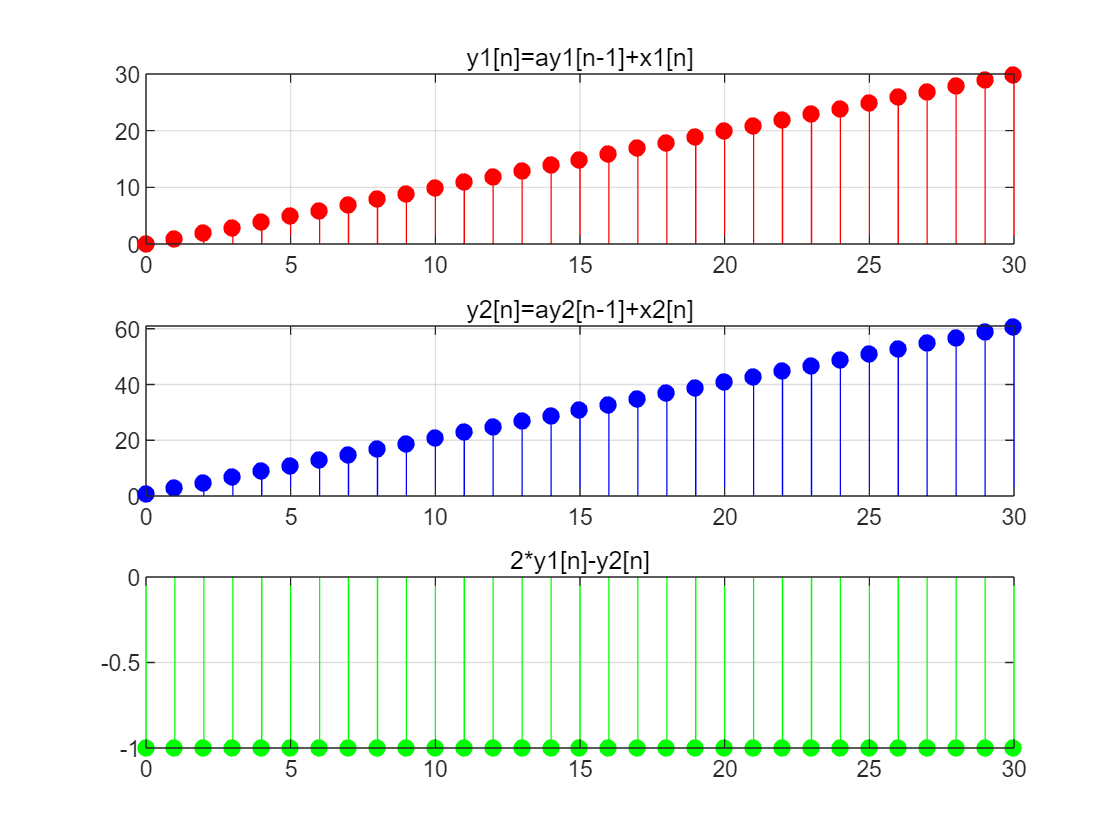

clc,clear,close all
a=1;
yn1=-1;
n=0:1:30;
x1=(n>=0);
x2=2*(n>=0);
y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);
figure
subplot(3,1,1),stem(n,y1,'r','filled'),title('y1[n]=ay1[n-1]+x1[n]');
grid on;
subplot(3,1,2),stem(n,y2,'b','filled'),title('y2[n]=ay2[n-1]+x2[n]');
grid on;
subplot(3,1,3),stem(n,2*y1-y2,'g','filled'),title('2*y1[n]-y2[n]')';
grid on;

在本节操作中，yn1应当也翻倍，才能够呈现线性系统的特点，而对于y1[n]和y2[n]，其y[-1]的初值相同，故2*y1[n]-y2[n]不等于0。

#### 1.5d 证明对于较大的n，初值不影响结果

分析：按题目要求绘制两图像比较

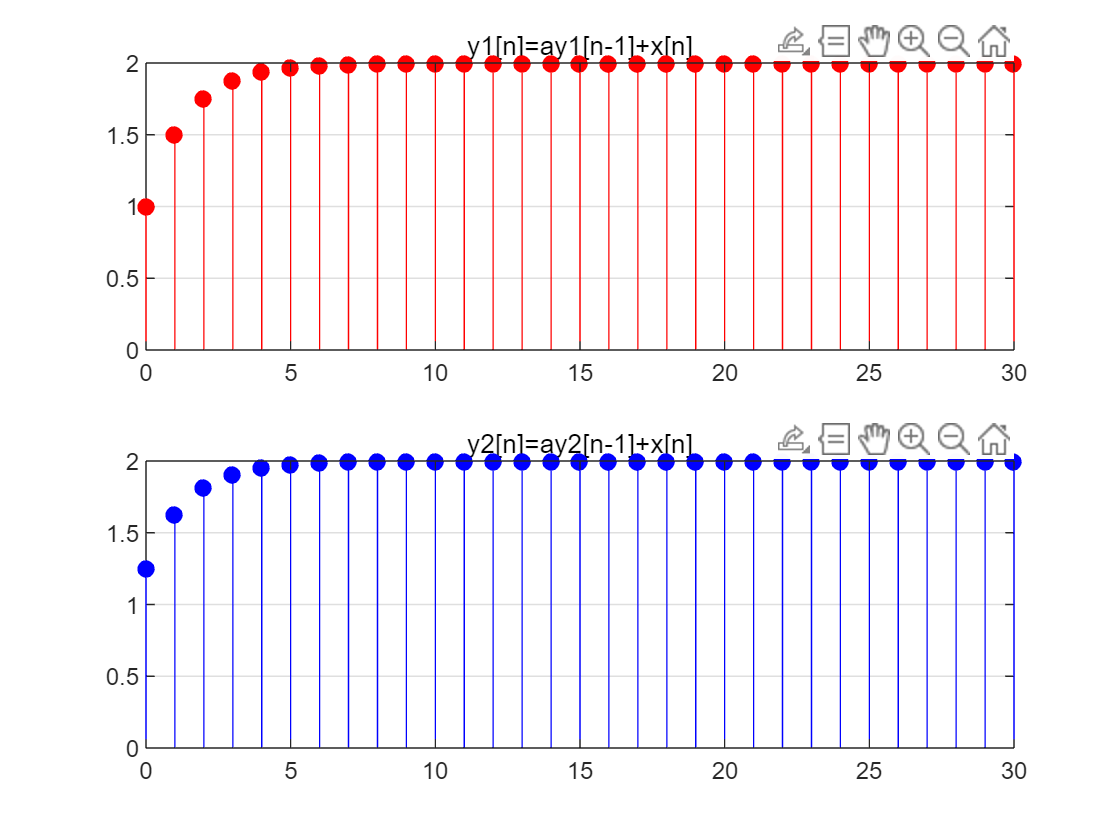

clc,clear,close all
a=0.5;
n=0:1:30;
x=(n>=0);
yn1=0;
yn2=0.5;
y1=diffeqn(a,x,yn1);
y2=diffeqn(a,x,yn2);
figure
subplot(2,1,1),stem(n,y1,'r','filled'),title('y1[n]=ay1[n-1]+x[n]');
grid on;
subplot(2,1,2),stem(n,y2,'b','filled'),title('y2[n]=ay2[n-1]+x[n]');
grid on;

根据图像可以观察到，当n较大时，不同的y[-1]不影响y[n]的值。

#### 1.5a 写函数实现y[n]=a*y[n-1]+x[n]

function y=diffeqn(a,x,yn1)
    y = zeros(1, length(x));
    y(1)=a*yn1+x(1);
    for i=2:length(x)
        y(i)=a*y(i-1)+x(i);
    end
    N=length(x);
    n=0:N-1;
end

### 课堂参与证明：

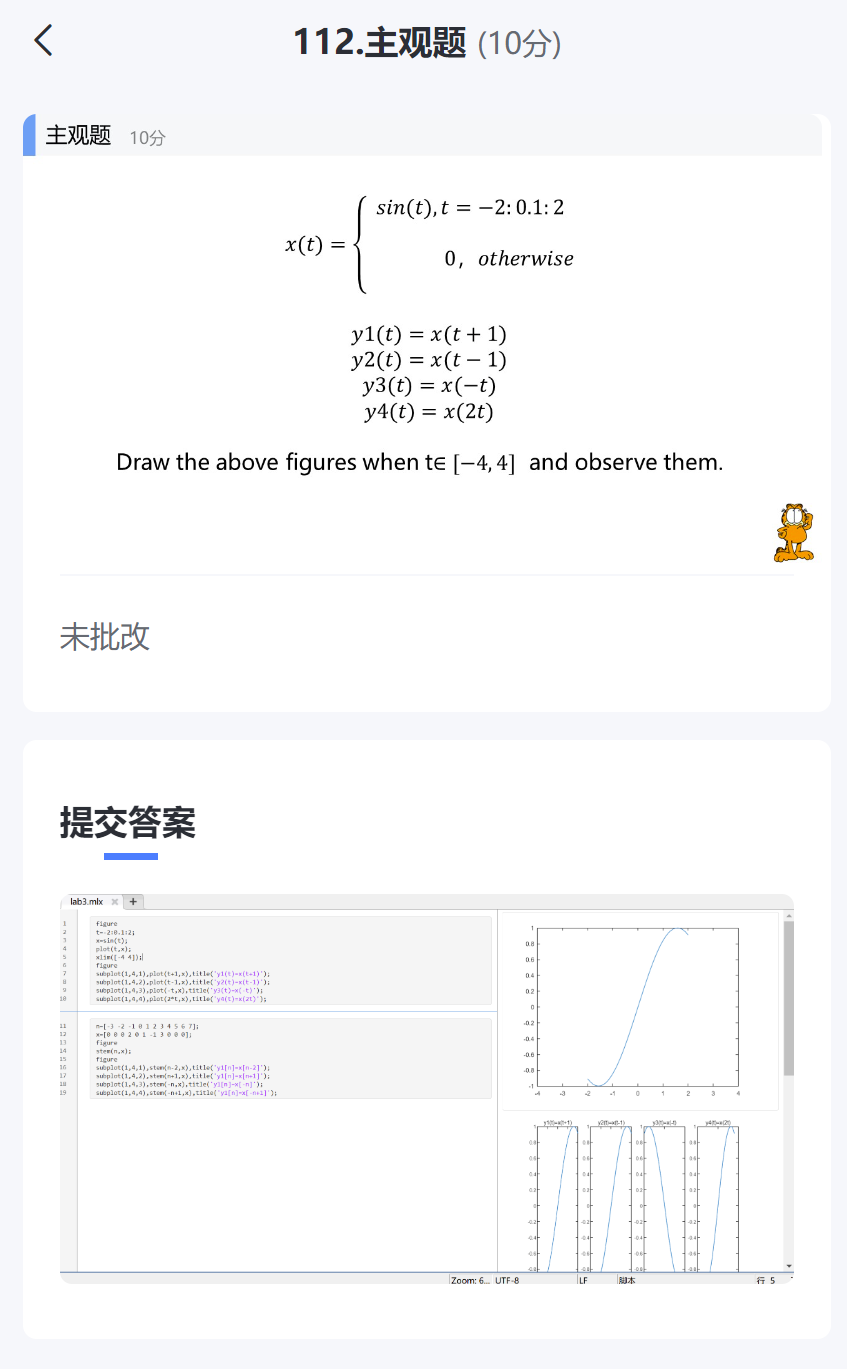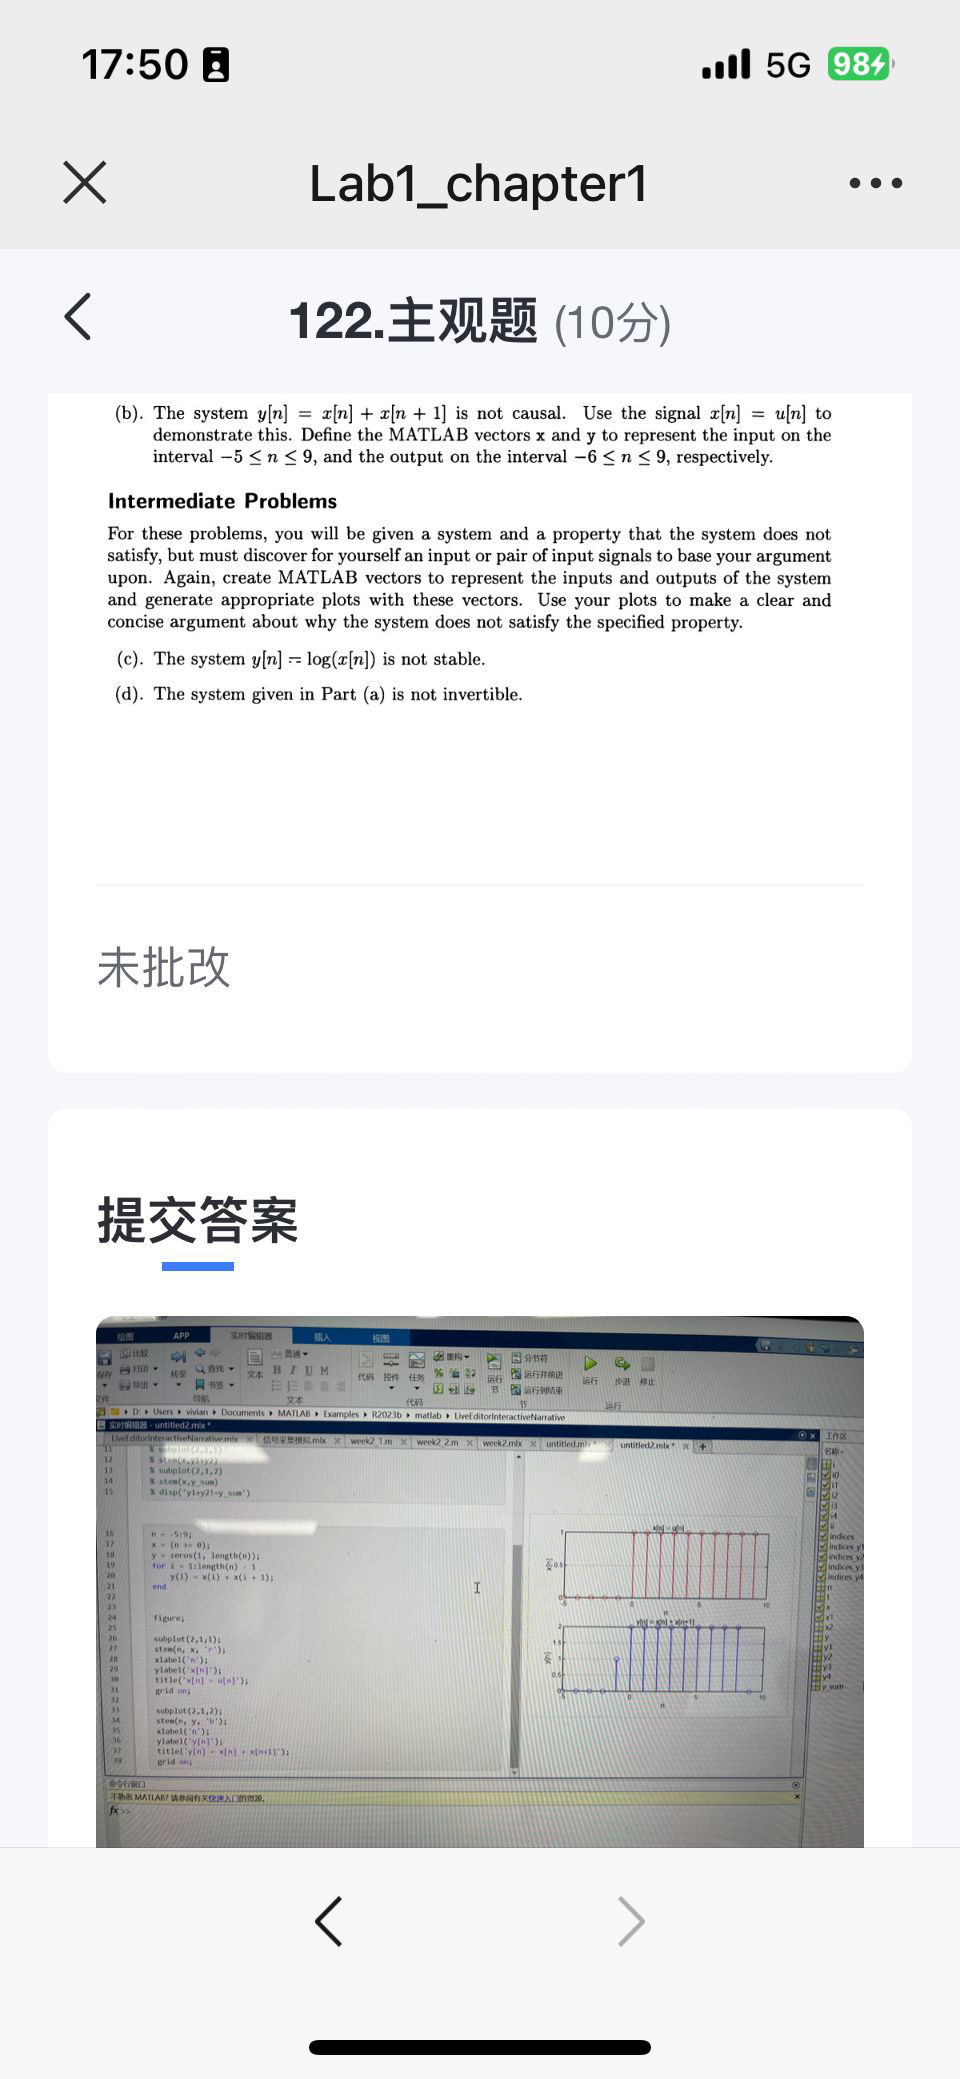

左图为应逸雯12210159，右图为陈薇羽12210460

### 自我评分：

应逸雯：10/10

陈薇羽：10/10